# This file is used for testing

## Initialization

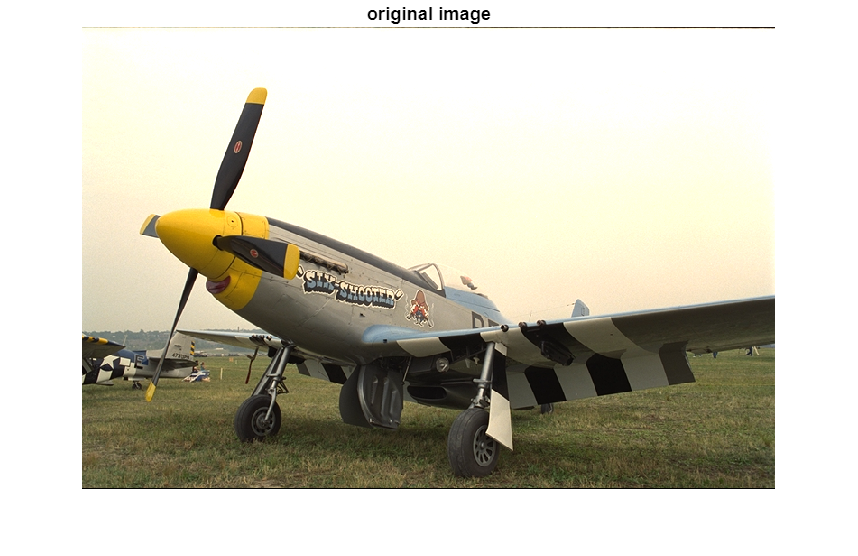

clc ; 
close all; 
clear all ;
original_image = imread('Image\kodim20.png') ; 
original_image = uint16(original_image) ; 
infor_image    = imfinfo('Image\kodim20.png') ; 
H = infor_image.Height ;
W = infor_image.Width; 
image_r  =  (original_image(:,:,1)); % red channel
image_g  =  (original_image(:,:,2)) ; % green channel
image_b  =  (original_image(:,:,3)) ; % blue channel
image_v_r  = image_r' ;                 
image_v_g  = image_g' ;                 
image_v_b =  image_b' ;    
% show original image 
imshow(uint8(original_image)); title('original image') ; 

## Write to text file

% write to file text with format of hexadecimal 
formatSpec = '%x\n' ; 
fileID_1 = fopen('in_img_r.txt','w'); 
fileID_2 = fopen('in_img_g.txt','w');  
fileID_3 = fopen('in_img_b.txt','w'); 
fprintf(fileID_1,formatSpec,image_v_r(:)) ;  
fprintf(fileID_2,formatSpec,image_v_g(:)) ; 
fprintf(fileID_3,formatSpec,image_v_b(:)) ;
fclose(fileID_1) ; 
fclose(fileID_2) ; 
fclose(fileID_3) ; 

## rgb2gray

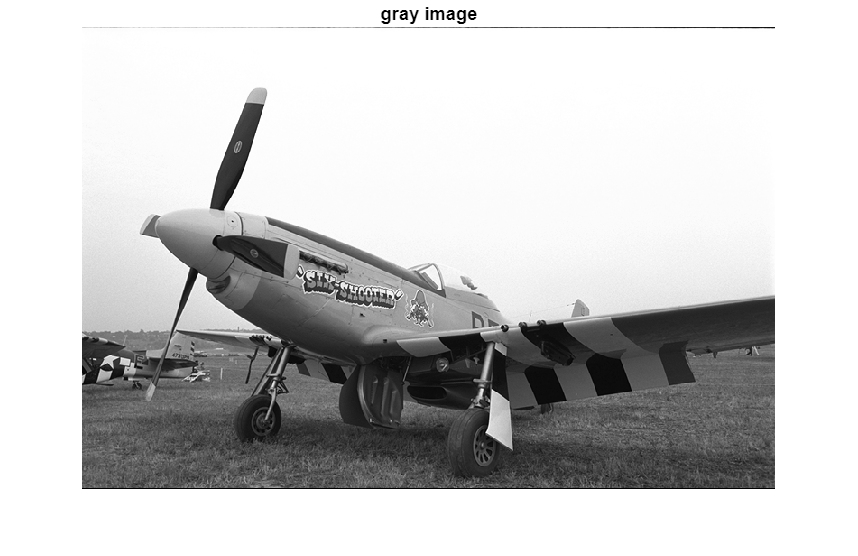

gray_image = ones(H,W) ; % gray image 
% gray_image = (red_channel*77+green_channel*150+blue_channel*29)/256
gray_image = uint16(image_r.*77+image_g.*150+image_b.*29) ;
gray_image = bitshift(gray_image,-8,"uint16") ; 
gray_image = uint8(gray_image) ; 
% show a gray image
clc; 
close all ; 
imshow(gray_image); title('gray image') ; 

## filtering

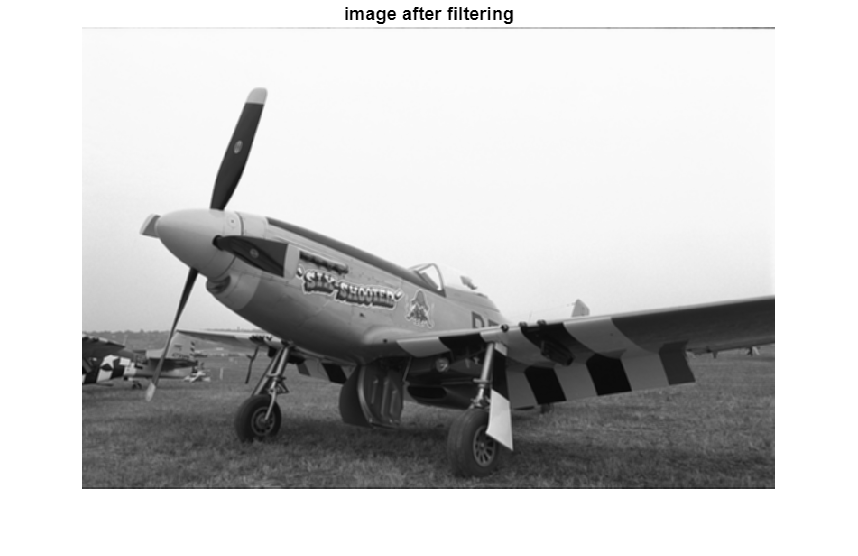

% filtering
filter_image = mean_filter(original_image) ;  
% show image
clc; 
close all ; 
imshow(filter_image) ; title('image after filtering');

## ehancing image

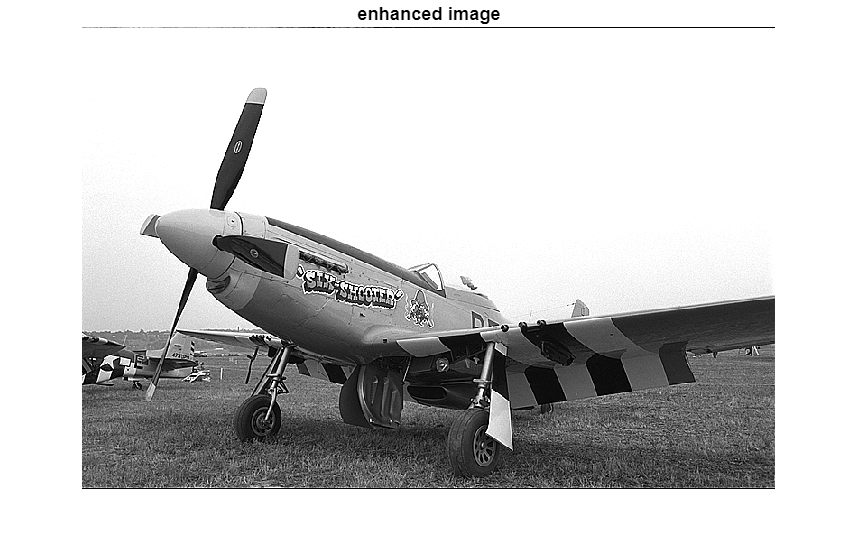

% ehancing image 
w_para = int32(3) ; 
edge = int32(gray_image) - int32(filter_image);   % extracting edge points                      
en_image = (int32(filter_image) + int32(w_para*edge)) ;  % enhanced image
en_image_1 = en_image ; 
less_than = en_image < 0 ; 
greater_than = en_image > 255 ; 
en_image(less_than) = 0 ; 
en_image(greater_than) = 255 ; 
en_image = uint8(en_image) ;   
clc; 
close all ; 
imshow(en_image) ; title('enhanced image');

## Read data from verilog result

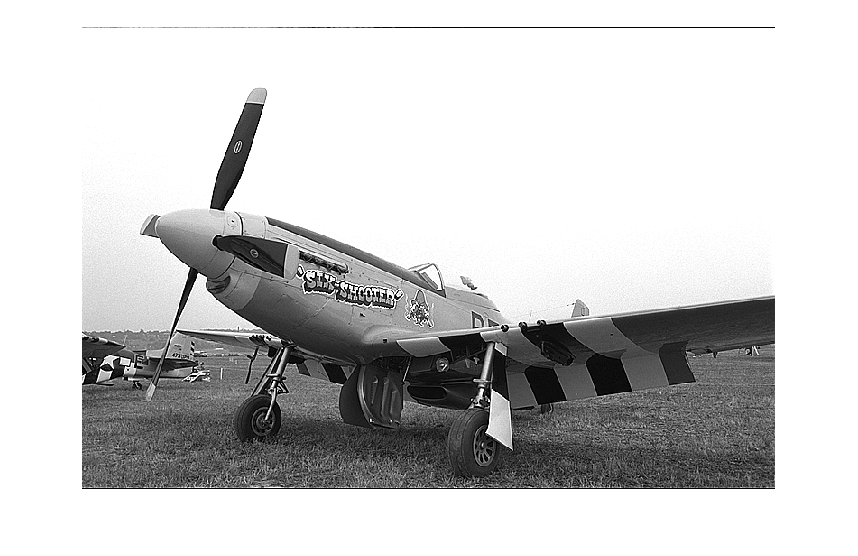

M = H; % Image height
N = W; % Image width
fileID = fopen('../py/out_y.txt', 'r');
data = fscanf(fileID, '%f'); % Read all numerical values
fclose(fileID);
% Reshape into three separate images
data = importdata('../py/out_y.txt') ;
ver_img_1 = reshape(data(1:M*N), [N,M]);
%ver_img_2 = reshape(data(M*N+1:2*M*N), [N, M]);
%ver_img_3 = reshape(data(2*M*N+1:3*M*N), [N, M]);
ver_img_1 = ver_img_1' ; 
%ver_img_2 = ver_img_2' ; 
%ver_img_3 = ver_img_3' ; 
imshow(ver_img_1,[]) ; 

## Difference

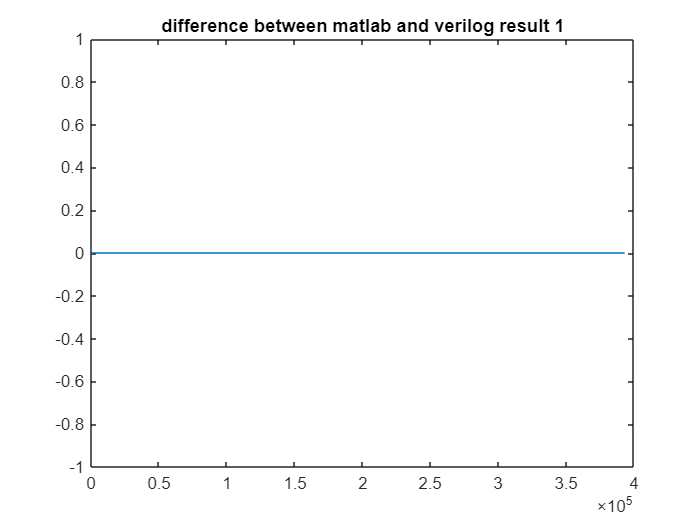

% differece between verilog and matlab
diff_1 = int32(ver_img_1) - int32(en_image) ;
%diff_2 = int32(ver_img_2) - int32(en_image) ; 
%diff_3 = int32(ver_img_3) - int32(en_image) ; 
% show difference   
clc ; 
close all ; 
figure(1) ; plot(diff_1(:)) ; title('difference between matlab and verilog result 1');

clc; 
close all ; 
%figure(2) ; plot(diff_2(:)) ; title('difference between matlab and verilog result 2');

clc;
close all ;
%figure(3) ; plot(diff_3(:)) ; title('difference between matlab and verilog result 3');

## Run this kernel if there are different in matlab and verilog results to fix errors

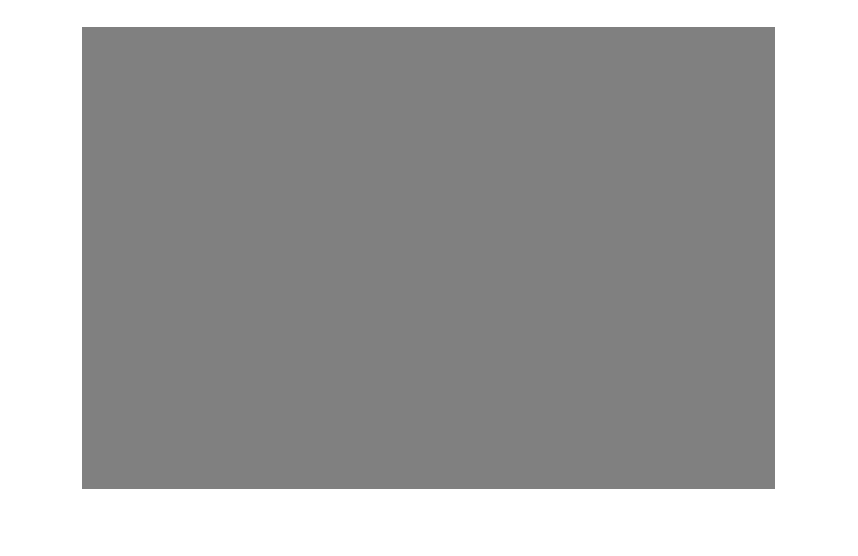

clc; 
close all ;
error_matrix = diff_1 ~=0 ; 
S = sparse(error_matrix) ;        % extract the coordinates of not-zero pixels
ver_point_errors = ver_img_1(S) ; % extract the value of unmatch pixels of verilog results
mat_point_errors = en_image(S) ;  % extract the value of unmatch pixels of matlab results
diff_errors = diff_1(S) ;
img_point = gray_image(S) ; 
en_error_point = en_image_1(S);
imshow(diff_1,[]) ;  